## **Preprocessing and analyzing EMG signals**

clc
clear

#### Importing raw data from a text file

path = "PP01/S1_MVC_delt_links.txt";

json = strrep(string(textscan(fopen(path, "r"),'%s',1,'delimiter','\n', 'headerlines',1)),"# ", "");

strlength(json)

ans = 560


header = jsondecode(extractBetween(json, 22, strlength(json) - 1));
raw_data = readmatrix(path, 'HeaderLines', 3, 'ExpectedNumVariables', 7);

number_of_channels = 5;

% Preallocation of resources

data = zeros(length(raw_data), number_of_channels);       % 5 channels
time = zeros(length(raw_data), 1);       % 1 time axis

#### Time data (seconds)

time = raw_data(:,1)./1000;

#### Raw data to mV

L = length(data);

% Sensor transfer function: EMG = ((((ADC/(2^n)) - 0.5)*VCC)/Gain) * 1000;
                         
gain = 1000;        % Gain - 1000
vcc = 3;            % VCC - 3V

for row = 1:L
    for channel = 1:number_of_channels

        % ADC - Value sampled from the channel
        % n - Number of bits of the channel

        n = header.resolution(channel);

        data(row, channel) = ((((raw_data(row, channel + 2) / (2^n)) - 0.5) * vcc) / gain) * 1000;
    end
end

#### Channels

`Channel 1 = M. Trapezius Descendens (Left)`

`Channel 2 = M. Trapezius Descendens (Right)`

`Channel 3 = M. Deltoīdeus Anterior (Left)`

`Channel 4 = M. Deltoīdeus Anterior (Right)`

`Channel 5 = M. Extensor Carpi Radialis (Dominant side)`

#### `Plotting the raw data`

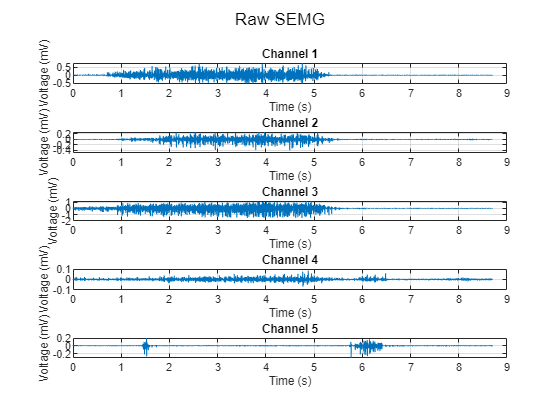

figure;

for channel = 1:number_of_channels
    subplot(number_of_channels, 1, channel);

    plot(time, data(:,channel));
    xlabel("Time (s)");
    ylabel("Voltage (mV)");

    grid;
    hold on;

    title("Channel " + channel);
end

sgtitle("Raw SEMG");
hold off

#### Fast Fourier Transform

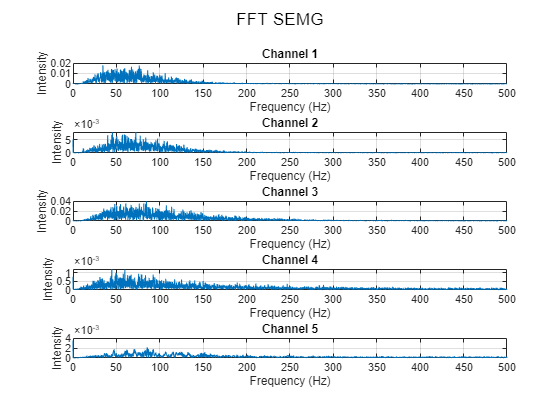

fs = header.samplingRate;        % Sampling frequency
f = fs * (0:(L/2)) / L;                             % Frequency range (axis)

figure;

for channel = 1:number_of_channels
    % Two sided spectrum (-Fmax:Fmax)
    p1 = fft(data(:, channel));

    % Normalisation of the power of the output ( divistion by L)
    p1 = abs(p1/L);

    % Single sided spectrum (positive part of two sided spectrum * 2)
    p1 = p1(1:L/2+1);
    p1(2:end-1) = 2 * p1(2:end-1);

    % Plot the fft data
    subplot(number_of_channels, 1, channel);

    plot(f, p1);
    xlabel("Frequency (Hz)");
    ylabel("Intensity");

    grid;
    hold on

    title("Channel " + channel);
end

sgtitle("FFT SEMG");
hold off

#### Outlier removal

stds = 3;

for channel = 1:number_of_channels
    data(:,channel) = filloutliers(data(:,channel),'linear','mean','ThresholdFactor', stds);
end

#### Bandpass filter

% Filter options

order = 4;
fnyq = fs/2;
fcuthigh = 20;
fcutlow = 200;

% Butterworth bandpass filter
[b,a] = butter(order, [fcuthigh, fcutlow] / fnyq, "bandpass");

for channel = 1:number_of_channels
    data(:,channel) = filtfilt(b, a, data(:,channel));       % Zero-phase digital filtering
end

#### Full wave rectification

% Preallocate resources
rec_signal = zeros(length(data), 3);

for channel = 1:number_of_channels
    rec_signal(:,channel) = abs(data(:,channel));
end

#### Plotting signal after the bandpass filter and rectification

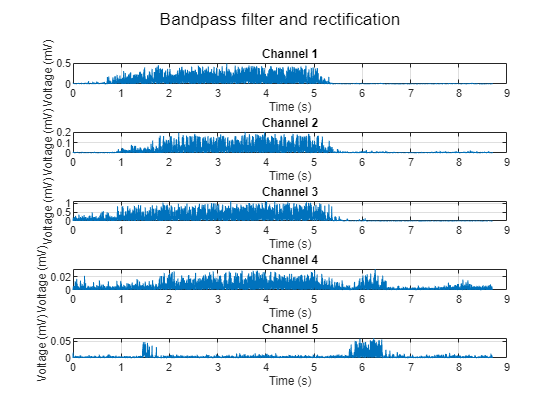

figure;

for channel = 1:number_of_channels
    subplot(number_of_channels, 1, channel);

    plot(time, rec_signal(:,channel));
    xlabel("Time (s)");
    ylabel("Voltage (mV)");

    grid;
    hold on;

    title("Channel " + channel);
end

sgtitle("Bandpass filter and rectification");
hold off;

#### RMS window

envelope = zeros(L, number_of_channels);

% Windo size in ms
window = 50;

for channel = 1:number_of_channels
    envelope(:, channel) = sqrt(movmean((rec_signal(:, channel).^2), window));      % RMS
end

#### MVC Normalisation

% Preallocate resources
% Maximum Voluntary Contraction (MVC)
MVC = [0 0 0 0 0];
MVC_normalised = zeros(L, number_of_channels);

% Find the MVC value for each channel (max value in raw data)
for channel = 1:number_of_channels
    MVC(:,channel) = max(data(:, channel));
end

% Divide signal by MVC and convert to percentage
for channel = 1:number_of_channels
    MVC_normalised(:,channel) = (envelope(:, channel) ./ MVC(1,channel)) .* 100;
end

#### Plotting the normalised envelope against the rectified signal

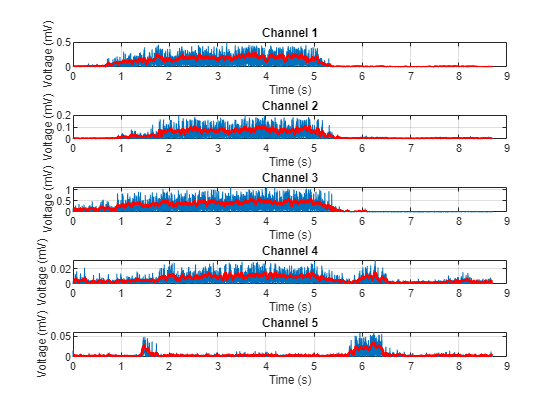

figure;

for channel = 1:number_of_channels
    subplot(number_of_channels, 1, channel);

    plot(time, rec_signal(:,channel));
    xlabel("Time (s)");
    ylabel("Voltage (mV)");

    grid;
    hold on;

    plot(time, envelope(:,channel), 'r', 'LineWidth', 2);

    title("Channel " + channel);
end

#### Export data

filename = 'patientdata.xlsx';

writematrix(MVC_normalised, filename, 'Sheet', 1, 'Range', 'A1')